# Run Your Function

p = struct("epoch", datetime("02-Sep-2014"), ...
           "inclination", 51.6461, ...
           "RAAN", 78.1961, ...
           "eccentricity", 3.662e-4, ...
           "argPerigee", 72.7758, ...
           "anomaly", 29.4412, ...
           "motion", 15.5017);
t = datetime("15-Dec-2014");
[lat, lon, r] = satelliteposition(p, t)

lat = -7.9468

lon = 25.5506

r = 6.7945e+03

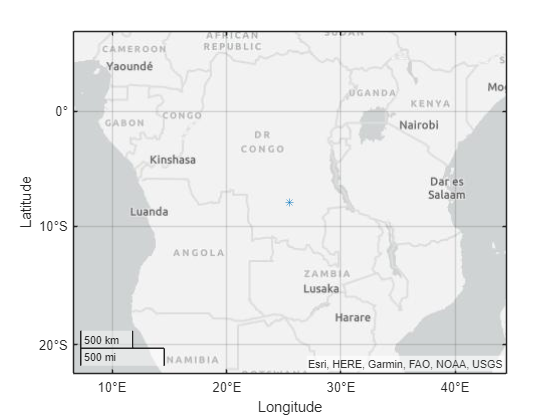

geoplot(lat, lon, "*")

# Determine (ECF) position of a satellite at a given time

[LAT,LON] = SATELLITEPOSITION(PARAMS) calculates the latitude (LAT) and longitude (LON), in Earth-centered fixed coordinates, of a satellite defined by the orbital parameters in the structure PARAMS for each time in the datetime array T.

[LAT,LON,RADIUS] = SATELLITEPOSITION(...) also returns the satellite's distance, in km, from the center of the Earth.

In the satellite application, only the `satelliteposition.mlx` file uses the `siderealtime` and `precession` functions. To reduce the number of files in the application, you will move `siderealtime` and `precession` into `satelliteposition.mlx` using local functions.

function [lat,lon,r] = satelliteposition(satparams,t)
% Extract parameters
inc = satparams.inclination;  % Inclination [deg]
e = satparams.eccentricity;   % Eccentricity []
n = satparams.motion;         % Mean Motion [rev/day]

% Semi-major axis
a = (2.975541313977700e+015/(2*pi*n)^2)^(1/3); % Constant is G*M_Earth

% Constant for converting between degrees and radians
rd = 180/pi;

% Calculate time since epoch
dt = days(t - satparams.epoch);
% Number of rotations since epoch time
ndt = n*dt;
% Current mean anomaly (Mt0 + fractional part of ndt)
M = mod(satparams.anomaly + 360*(ndt - floor(ndt)),360)/rd;
% Solve Kepler's equation to get eccentric anomaly
E = M;
f = e*sin(E) + M;
while norm(E-f) > 1e-6
    E = f;
    f = e*sin(E) + M;
end
% Calculate true anomaly
nu = 2*rd*atan2(sqrt((1+e)/(1-e))*sin(E/2),cos(E/2));

% Account for precession of orbit (RAAN and Arg of Perigee)
[aWt,wt] = precession(a,e,inc,ndt,satparams.RAAN,satparams.argPerigee);
% Argument of Latitude
mu = mod(wt + nu,360);
% Difference in RA between satellite's geocentric position and RAAN
Da = acosd(cosd(mu) ./ sqrt(1-sind(inc)^2*sind(mu).^2));
idx = ((inc < 90) & (mu > 180)) | ((90 < inc) & (180 > mu));
Da(idx) = 360 - Da(idx);

% Geocentric coordinates (RA and DEC)
ag = mod(aWt + Da,360);
dg = sign(sind(mu)).*acosd(cosd(mu)./cosd(Da));

% Radial distance
r = a*(1-e^2)./(1+e*cosd(nu));

lat = dg;
% Get longitude by shifting by Greenwich ST (then wrap to [-180 180])
lon = mod(ag - 15*siderealtime(t,0) + 180,360) - 180;
end

function LST = siderealtime(t,lon)
% Determines local sidereal time
%
% LST = SIDEREALTIME(T,LON) calculates the sidereal time given the (UTC)
% time T [datetime] and the longitudinal position LON [in degrees].

% J2000 (shifted Julian date)
D = days(t - datetime(2000,1,1,12,0,0));
% Greenwich mean sidereal time
GMST = mod(18.697374558 + 24.06570982441908*D,24);
% Adjust for local longitude
LST = mod(GMST + 1.0027379*lon/15,24);
end

function [aWt,wt] = precession(a,e,inc,ndt,aW,w)
% Determines effects of precession on satellite location
%
% [AWT,WT] = PRECESSION(A,E,I,NDT,AW,W) calculates the right ascension of
% the ascending node and the argument of perigee for the satellite due to
% precession. A is the semi-major axis, E is the eccentricity, I is the
% inclination, NDT is the number of rotations since epoch, aW is the
% original value for the right ascension of the ascending node and w is the
% original argument of perigee.
%
% Example:
%    [aWt,wt] = precession(6768,0.0022,51.6389,-170.28,187.86,10.63);

aE = 1;
a1 = a/6378.135;
J2 = 1.082616e-3;
d1 = (3*J2*aE^2*(3*cosd(inc)^2 - 1))/(4*a1^2*(1-e^2)^(3/2));
a0 = -a1*(134*d1^3/81 + d1^2 + d1/3 - 1);
p0 = a0*(1-e^2);
aWt = aW + 360*(-3*J2*aE^2*ndt*cosd(inc) / (2*p0^2));
wt = w + 360*(3*J2*aE^2*ndt*(5*cosd(inc)^2 - 1)/(4*p0^2));
end